rawDataPath_cells_media = '/home/mxwbio/Data/JG_25_12_08_M231s/251208/003425/Record/000002/data.raw.h5';
rawDataPath_media_media = '/home/mxwbio/Data/JG_25_12_08_M231s/251208/003486/Record/000001/data.raw.h5';

rawDataPath_cells_T0 = '/home/mxwbio/Data/JG_25_12_08_M231s/251215/P003425/Record/000006/data.raw.h5';
rawDataPath_cells_T30 = '/home/mxwbio/Data/JG_25_12_08_M231s/251215/P003425/Record/000010/data.raw.h5';
rawDataPath_cells_T60 = '/home/mxwbio/Data/JG_25_12_08_M231s/251215/P003425/Record/000014/data.raw.h5';

rawDataPath_cells_D1 = '/home/mxwbio/Data/JG_25_12_08_M231s/251216/P003425/Record/000018/data.raw.h5';
rawDataPath_cells_D2 = '/home/mxwbio/Data/JG_25_12_08_M231s/251217/P003425/Record/000026/data.raw.h5';
rawDataPath_cells_D3 = '/home/mxwbio/Data/JG_25_12_08_M231s/251218/P003425/Record/000030/data.raw.h5';
rawDataPath_cells_D4 = '/home/mxwbio/Data/JG_25_12_08_M231s/251219/P003425/Record/000038/data.raw.h5';

rawDataPath_media_T0 = '/home/mxwbio/Data/JG_25_12_08_M231s/251215/P003486/Record/000008/data.raw.h5';
rawDataPath_media_T30 = '/home/mxwbio/Data/JG_25_12_08_M231s/251215/P003486/Record/000012/data.raw.h5';
rawDataPath_media_T60 = '/home/mxwbio/Data/JG_25_12_08_M231s/251215/P003486/Record/000016/data.raw.h5';

rawDataPath_media_D1 = '/home/mxwbio/Data/JG_25_12_08_M231s/251216/P003486/Record/000020/data.raw.h5';
rawDataPath_media_D2 = '/home/mxwbio/Data/JG_25_12_08_M231s/251217/P003486/Record/000025/data.raw.h5';
rawDataPath_media_D3 = '/home/mxwbio/Data/JG_25_12_08_M231s/251218/P003486/Record/000032/data.raw.h5';
rawDataPath_media_D4 = '/home/mxwbio/Data/JG_25_12_08_M231s/251219/P003486/Record/000040/data.raw.h5';

rawData_cells_media = mxw.fileManager(rawDataPath_cells_media);
rawData_cells_T0 = mxw.fileManager(rawDataPath_cells_T0);
rawData_cells_T30 = mxw.fileManager(rawDataPath_cells_T30);
rawData_cells_T60 = mxw.fileManager(rawDataPath_cells_T60);

rawData_cells_D1 = mxw.fileManager(rawDataPath_cells_D1);
rawData_cells_D2 = mxw.fileManager(rawDataPath_cells_D2);
rawData_cells_D3 = mxw.fileManager(rawDataPath_cells_D3);
rawData_cells_D4 = mxw.fileManager(rawDataPath_cells_D4);

rawData_media_media = mxw.fileManager(rawDataPath_media_media);
rawData_media_T0 = mxw.fileManager(rawDataPath_media_T0);
rawData_media_T30 = mxw.fileManager(rawDataPath_media_T30);
rawData_media_T60 = mxw.fileManager(rawDataPath_media_T60);

rawData_media_D1 = mxw.fileManager(rawDataPath_media_D1);
rawData_media_D2 = mxw.fileManager(rawDataPath_media_D2);
rawData_media_D3 = mxw.fileManager(rawDataPath_media_D3);
rawData_media_D4 = mxw.fileManager(rawDataPath_media_D4);

electrodes = 894:894;
numSeconds = 10;

[PSD_cells_media,freq] = processRawData(rawData_cells_media,electrodes,numSeconds);
[PSD_cells_T0,~] = processRawData(rawData_cells_T0,electrodes,numSeconds);
[PSD_cells_T30,~] = processRawData(rawData_cells_T30,electrodes,numSeconds);
[PSD_cells_T60,~] = processRawData(rawData_cells_T60,electrodes,numSeconds);

[PSD_cells_D1,~] = processRawData(rawData_cells_D1,electrodes,numSeconds);
[PSD_cells_D2,~] = processRawData(rawData_cells_D2,electrodes,numSeconds);
[PSD_cells_D3,~] = processRawData(rawData_cells_D3,electrodes,numSeconds);
[PSD_cells_D4,~] = processRawData(rawData_cells_D4,electrodes,numSeconds);

[PSD_media_media,~] = processRawData(rawData_media_media,electrodes,numSeconds);
[PSD_media_T0,~] = processRawData(rawData_media_T0,electrodes,numSeconds);
[PSD_media_T30,~] = processRawData(rawData_media_T30,electrodes,numSeconds);
[PSD_media_T60,~] = processRawData(rawData_media_T60,electrodes,numSeconds);

[PSD_media_D1,~] = processRawData(rawData_media_D1,electrodes,numSeconds);
[PSD_media_D2,~] = processRawData(rawData_media_D2,electrodes,numSeconds);
[PSD_media_D3,~] = processRawData(rawData_media_D3,electrodes,numSeconds);
[PSD_media_D4,~] = processRawData(rawData_media_D4,electrodes,numSeconds);

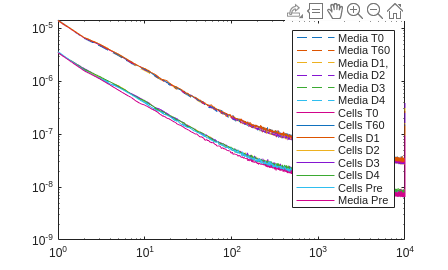

clf;

loglog(freq,sqrt(PSD_media_T0),'--');

% hold on;
% loglog(freq,sqrt(PSD_media_T30),'--');
% hold off;
hold on;
loglog(freq,sqrt(PSD_media_T60),'--');
hold off;

hold on;
loglog(freq,sqrt(PSD_media_D1),'--');
hold off;
hold on;
loglog(freq,sqrt(PSD_media_D2),'--');
hold off;
hold on;
loglog(freq,sqrt(PSD_media_D3),'--');
hold off;
hold on;
loglog(freq,sqrt(PSD_media_D4),'--');
hold off;

hold on;
loglog(freq,sqrt(PSD_cells_T0));
hold off;
% hold on;
% loglog(freq,sqrt(PSD_cells_T30));
% hold off;
hold on;
loglog(freq,sqrt(PSD_cells_T60));
hold off;

hold on;
loglog(freq,sqrt(PSD_cells_D1));
hold off;
hold on;
loglog(freq,sqrt(PSD_cells_D2));
hold off;
hold on;
loglog(freq,sqrt(PSD_cells_D3));
hold off;
hold on;
loglog(freq,sqrt(PSD_cells_D4));
hold off;

hold on;
loglog(freq,sqrt(PSD_cells_media));
hold off;
hold on;
loglog(freq,sqrt(PSD_media_media));
hold off;

%legend("Media T0","Media T30","Media T60","Media D1,","Media D2","Media D3","Media D4","Cells T0","Cells T30","Cells T60","Cells D1","Cells D2","Cells D3","Cells D4");
legend("Media T0","Media T60","Media D1,","Media D2","Media D3","Media D4","Cells T0","Cells T60","Cells D1","Cells D2","Cells D3","Cells D4","Cells Pre","Media Pre");

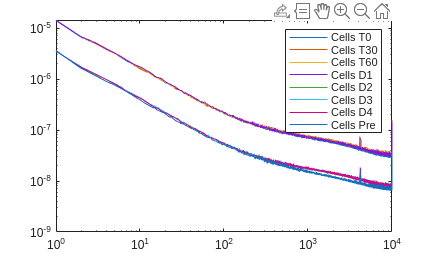


loglog(freq,sqrt(PSD_cells_media));


hold on;
loglog(freq,sqrt(PSD_media_media));
hold off;
hold on;
loglog(freq,sqrt(PSD_cells_T0));
hold off;
hold on;
loglog(freq,sqrt(PSD_cells_D4));
hold off;
legend("Cells Pre","Media Pre","t0,");

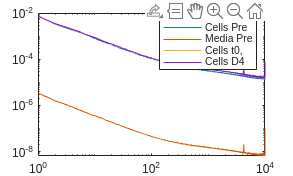


function [rawTracesSubset] = getRawTracesSubset(rawData,electrodes,numSeconds)
   
    fs = 20000;
    
    [rawTraces,~,~] = rawData.extractRawData(fs,(numSeconds*fs),'files',1);
    rawTracesSubset = rawTraces(:,electrodes);
   
    rawTracesSubset = rawTracesSubset./1000000;

end

function [filteredTraces] = getFilteredTraces(rawTraces)

    fs = 20000;

    [sos,g] = butter(1,0.01/(fs/2),"high");
    filteredTraces = filtfilt(sos,g,rawTraces);
end

function [avPSD,freqs] = getAveragePSD(filteredTraces,numSeconds)

    fs = 20000;
    resolution = 1/numSeconds;
    nfft = fs/resolution;
    window = hann(nfft); %len?
    overlap = 0;

    
    [PSDs,freqs] = pwelch(filteredTraces,window,overlap,nfft,fs);
    avPSD = sum(PSDs,2)/size(PSDs,2);

end

function [PSD,freq] = processRawData(rawData,electrodes,numSeconds)
    rawTracesSubset = getRawTracesSubset(rawData,electrodes,numSeconds);
    filteredTraces = getFilteredTraces(rawTracesSubset);
    [PSD,freq] = getAveragePSD(filteredTraces,numSeconds);
end